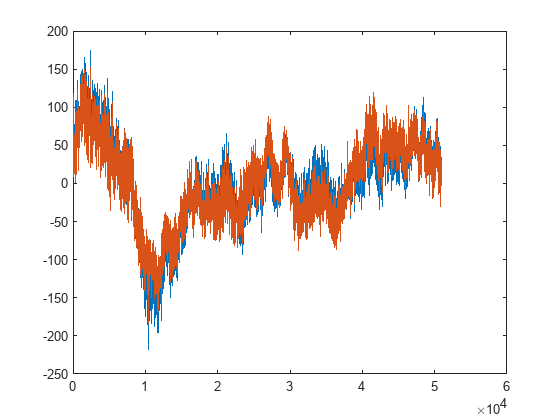

clc; clear all; close all;

load("SSVEP1_14Hz.mat")
x = EEGdata;
plot(x(1, :)-mean(x(1, :)))
hold on
plot(x(2, :)-mean(x(2, :)))
hold off

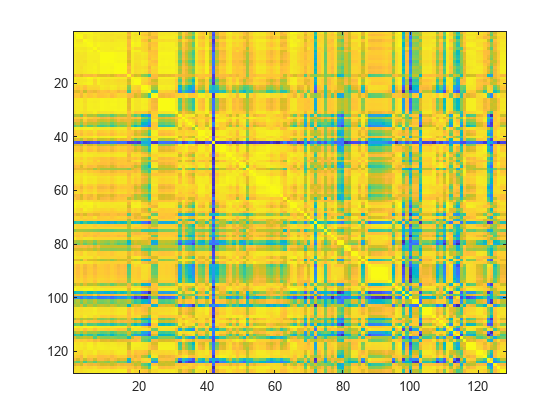


figure()

x = x-mean(x, 2);
% normalization
x = x./sqrt(mean(x.^2, 2));
imagesc(abs(x*x'/length(x)))

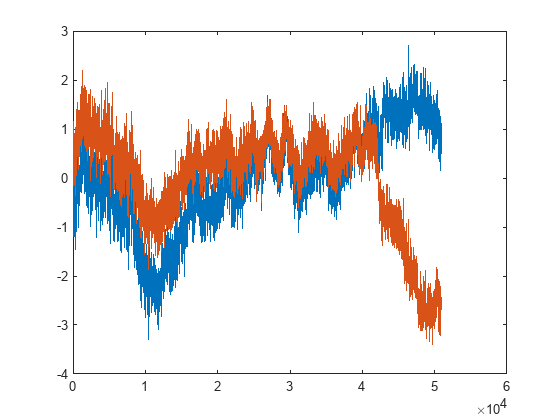


figure()
plot(x(41,:))
hold on
plot(x(42,:))
hold off

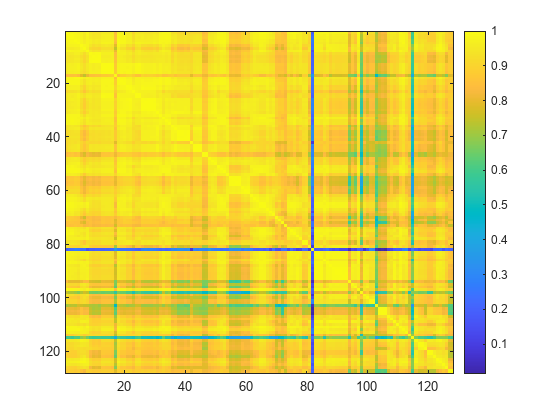


figure()

window = 100;
for i = 1:window:size(x, 2)
    upper_index = min(i+window-1, size(x, 2));
    xx = x(:, i:upper_index);
    xx = xx-mean(xx, 2);
    % normalization
    xx = xx./sqrt(mean(xx.^2, 2));
    C = abs(xx*xx'/size(xx, 2));
    imagesc(C)
    colorbar()
    drawnow()
end